% ==========================
% NACA 4-Digit Airfoil Plot
% ==========================
% This script plots the upper/lower surfaces and camber lines for:
%   - NACA 2312
%   - NACA 2324
%   - NACA 4412
%   - NACA 4424
%
% where:
%   m = maximum camber (percentage of chord)
%   p = location of maximum camber (percentage of chord)
%   t = thickness (percentage of chord)
%
% Author: [Your Name]
% Date:   [Date]

clear; clc; close all;

## --- Main script portion: define airfoils and plot ---

(m, p, t) all in fraction-of-chord terms

airfoilDefs = { ...
    'NACA 2312', NACA(0.02, 0.3, 0.12); ...
    'NACA 2324', NACA(0.02, 0.3, 0.24); ...
    'NACA 4412', NACA(0.04, 0.4, 0.12); ...
    'NACA 4424', NACA(0.04, 0.4, 0.24); ...
    };

figure('Name','NACA 4-Digit Airfoils','NumberTitle','off');
hold on; grid on;

colors = lines(size(airfoilDefs,1));  % Just to have distinct colors

for i = 1:size(airfoilDefs,1)
    name = airfoilDefs{i,1};

    [x, yc, xu, yu, xl, yl] = airfoilDefs{i,2}.naca_airfoil();

    % Plot upper surface
    plot(xu, yu, 'Color', colors(i,:), 'LineWidth', 1.2, ...
        'DisplayName',[name ' Upper']);
    % Plot lower surface
    plot(xl, yl, 'Color', colors(i,:), 'LineWidth', 1.2, ...
        'LineStyle','-', 'HandleVisibility','off');
    % Plot camber line (dashed)
    plot(x, yc, '--', 'Color', colors(i,:), ...
        'LineWidth', 1.0, 'HandleVisibility','off');
end

xc =          0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462


xc =          0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462


xc =          0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462


xc =          0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462


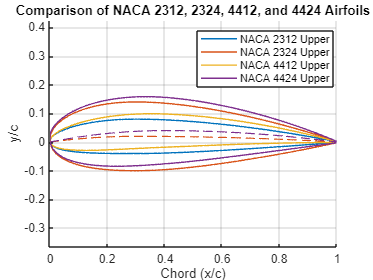


title('Comparison of NACA 2312, 2324, 4412, and 4424 Airfoils');
xlabel('Chord (x/c)');
ylabel('y/c');
axis equal;
legend('Location','best');
hold off;